# Actividad

# Poryecto Regresion

#### Fecha:

fecha = datetime('now', 'Format', 'dd-MM-yyyy');
disp(['Fecha actualizada: ', char(fecha)])

Fecha actualizada: 06-07-2024


#### Objetivos:

- **Desde Open Energy Data Initiative, seleccionar un archivo CSV cualquiera de cualquier estado: **[https://openei.org/datasets/files/961/pub/COMMERCIAL_LOAD_DATA_E_PLUS_OUTPUT/](https://openei.org/datasets/files/961/pub/COMMERCIAL_LOAD_DATA_E_PLUS_OUTPUT/)

- Definir la variable de salida y las variables de entrada del sistema

- **Definir basado en alguna aplicacion, **Cambiar la resolucion temporal de los datos: n Dias** (Ajustar nhoras)
**

- Seleccionar Variables o caracteristicas empleando la matriz de correlacion **(Ajustar el threshold)**

- **Seleccionar el algortimo de ML con un menos error de prediccion empleando el toolbox de Matlab Regression Learner**

- Dividir el dataset en 70% para entrenar y 30% validar **(Ajustar el PSplit)**

- Usando el algoritmo de ML se entrena el modelo de regression

- Cargar y validar el modelo entrenado

- Graficar el valor predecido vs el valor real

- **Analizar el resultado obtenido y tratar de reducir el error**

#### Nombre:

- sunombre

#### Repository:

- [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

#### Librarys:

- [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- [https://es.mathworks.com/help/matlab/ref/ls.htm](https://es.mathworks.com/help/matlab/ref/ls.htm)

- [https://es.mathworks.com/help/matlab/ref/matlab.git.gitrepository.discardchanges.html#d126e406558](https://es.mathworks.com/help/matlab/ref/matlab.git.gitrepository.discardchanges.html#d126e406558)

## Paso 0: Descartar cualquier cambio realizado en el repositorio clonado

%Version Online, Opcion 1:
% Source Control -> Discard all changes
% Source Control -> git pull

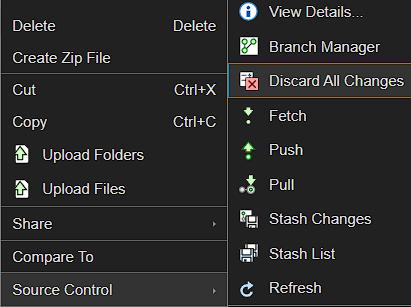

%Version Online, Opcion 2:
% repo = gitrepo;
% discardChanges(repo,repo.ModifiedFiles);
% Source Control -> git pull

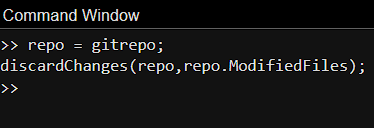

% Version para PC, en el Bash del Git:
% git status
% git reset --hard
% Git pull

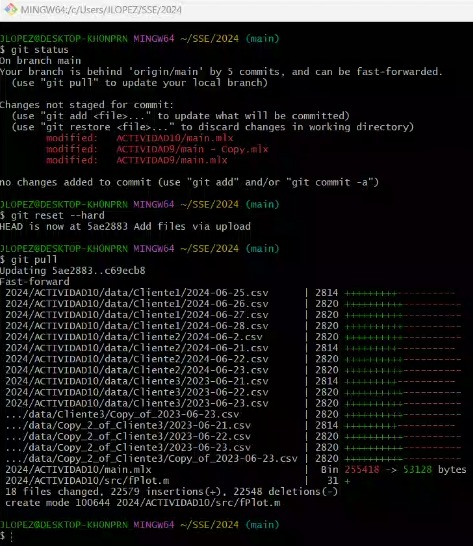

## Paso 1: Limpiar variables y linea de comandos

clear % Para borrar el workspace y liberar memoria RAM
clc  % Limpiar el command window

## Paso 2.- Configuración de carpeta ./src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

## **Paso 3- Configuranción de carpeta de ./data para datasets**

%Nombre de la carpeta donde estan los archvios csv
datapath=fullfile('./data/');

## **Paso 4- **Desde Open Energy Data Initiative, seleccionar un archivo CSV cualquiera de cualquier estado

### Informacion del dataset

- USA_AK_FAIRBANKS.csv

- USA_AK_Anchorage.Intl.AP.702730_TMY3/

cd data %Comando linux para entrar una carpeta
httpsUrl = "https://openei.org/datasets/files/961/pub/COMMERCIAL_LOAD_DATA_E_PLUS_OUTPUT/USA_AK_Anchorage.Intl.AP.702730_TMY3";
dataUrl = strcat(httpsUrl,"/RefBldgSmallHotelNew2004_v1.3_7.1_8A_USA_AK_FAIRBANKS.csv");
DataFile = "RefBldgSmallHotelNew2004_v1.3_7.1_8A_USA_AK_FAIRBANKS.csv";
DataFileFullPath = websave(DataFile,dataUrl);
cd .. %Comando linux para salir de la carpeta
clear httpsUrl dataUrl DataFile DataFileFullPath

## **Paso 4- Buscar los nombres y **Cargar los datos **de todos los archivos dentro de la carpeta ./data**

%Leer un archivo csv y lo carga como una tabla
filename = FindCSV(datapath);
maxnames=size(filename,1);
% Dataset es una tabla donde cada columna es una variable con su 
% respectivo nombre
index=1; % El archivo que quiero que lea desde la carpeta data
filename(index).name

ans = 'RefBldgSmallHotelNew2004_v1.3_7.1_8A_USA_AK_FAIRBANKS.csv'

Dataset=fLoadTableCSV_index(filename,datapath,index)

Dataset = 8760×11 table
         Date_Time         Electricity_Facility_kW__Hourly_    Fans_Electricity_kW__Hourly_    Cooling_Electricity_kW__Hourly_    Heating_Electricity_kW__Hourly_    InteriorLights_Electricity_kW__Hourly_    InteriorEquipment_Electricity_kW__Hourly_    Gas_Facility_kW__Hourly_    Heating_Gas_kW__Hourly_    InteriorEquipment_Gas_kW__Hourly_    WaterHeater_WaterSystems_Gas_kW__Hourly_
    ___________________    ________________________________    ____________________________    _______________________________    _______________________________    ______________________________________    _________________________________________    ________________________<

## **Paso 5- Extraer nombres de variables y crear datetime**

% Extraer todos los nombres de variables de la tabla
% Se hace el cast de cell a string
varnames=string(Dataset.Properties.VariableNames);
% Eliminar el primero nombbre de variable
varnames=varnames(2:end)';

% Esto es para eliminar el warning de los legend en el plot
%LegendNames=char(varnames);
%LegendNames=LegendNames(:,1:15);
%LegendNames=[LegendNames char(65*ones([size(varnames,1),1]))];
%LegendNames=string(LegendNames);

% Crear datatime con una frecuencia de muestreo de un dato por hora segun el
% dataset
%Time = Start Time: Step Time: End Time
time = datetime(2004, 1, 1):hours(1):datetime(2004, 12, 31);
% Se elimina el primer valor
time=time(1,2:end)';

% para agregar una nueva variables en la tabla
%Dataset.('Time_Stamp')=time;

## **Paso 6- Graficar todas las variables**

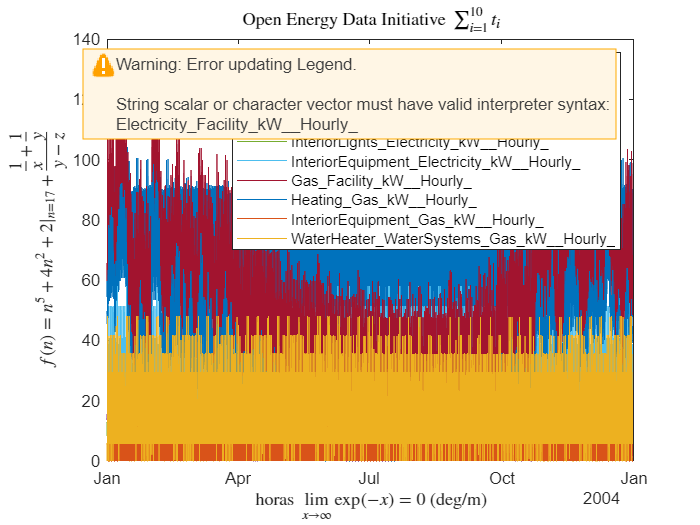

figure;
% Dataset
Variable1=Dataset.(varnames(1));
plot(time,Variable1)
hold on
Variable2=Dataset.(varnames(2));
plot(time,Variable2)
Variable3=Dataset.(varnames(3));
plot(time,Variable3)
Variable4=Dataset.(varnames(4));
plot(time,Variable4)
Variable5=Dataset.(varnames(5));
plot(time,Variable5)
Variable6=Dataset.(varnames(6));
plot(time,Variable6)
Variable7=Dataset.(varnames(7));
plot(time,Variable7)
Variable8=Dataset.(varnames(8));
plot(time,Variable8)
Variable9=Dataset.(varnames(9));
plot(time,Variable9)
Variable10=Dataset.(varnames(10));
plot(time,Variable10)

hold off
%legend(LegendNames);
legend(varnames);

% tambien se puede usar latex para los lables y titles
% https://en.wikibooks.org/wiki/LaTeX/Mathematics
title('Open Energy Data Initiative $ \sum_{i=1}^{10} t_i $', 'interpreter', 'latex');
xlabel('horas $ \lim\limits_{x \to \infty} \exp(-x) = 0 $ (deg/m)', 'interpreter', 'latex')
ylabel(' $ f(n) = n^5 + 4n^2 + 2 |_{n=17} + \frac{\frac{1}{x}+\frac{1}{y}}{y-z} $', 'interpreter', 'latex')

clear filename maxnames index
clear Variable1 Variable2 Variable3 Variable4 Variable5 Variable6 ...
    Variable7 Variable8 Variable9 Variable10

## **Paso 7- Definir la variable de salida y las variables de entrada del sistema**

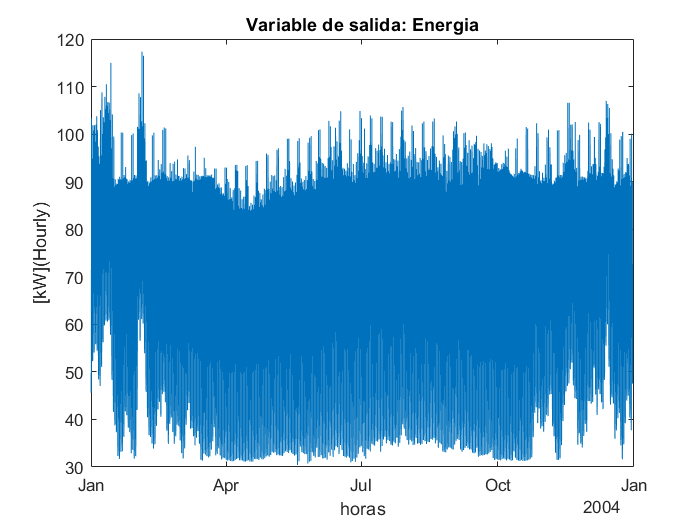

figure;
% Dataset
output=Dataset.(varnames(1));
plot(time,output)
title('Variable de salida: Energia');
xlabel('horas')
ylabel('[kW](Hourly)')

% Estamos usando las variables como caracteristicas
input=[Dataset.(varnames(2)) Dataset.(varnames(3))...
    Dataset.(varnames(4)) Dataset.(varnames(5))...
    Dataset.(varnames(6)) Dataset.(varnames(7))...
    Dataset.(varnames(8)) Dataset.(varnames(9))...
    Dataset.(varnames(10))];

## **Paso 8- Cambiar la resolucion temporal de los datos: Dias, Semanas, meses**

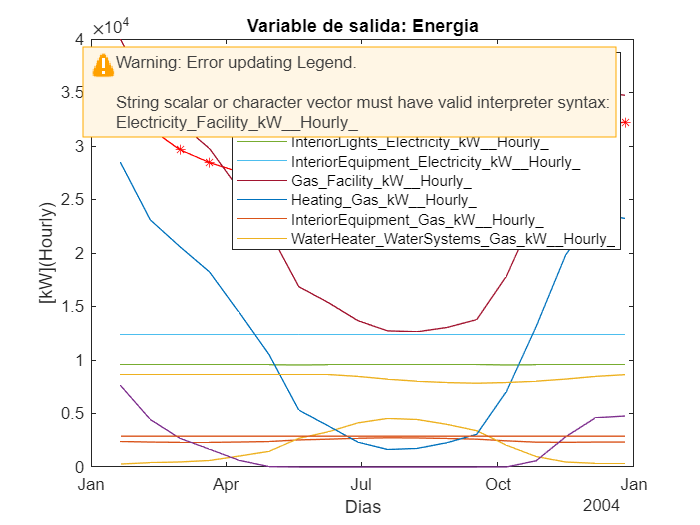

%Variable de conversion de horas a Dias, Semanas o meses
nhoras=24*20; %dias

outputDias=[];
inputDias=[];
for i=1:nhoras:size(output,1)-(nhoras-1)
    outputDias=[outputDias;sum(output(i:i+nhoras-1),1)];%1+23 =24
    inputDias=[inputDias;sum(input(i:i+nhoras-1,:),1)];%1+23 =24
end

% Crear datatime con una frecuencia de muestreo de un dato por hora segun el
% dataset
%Time = Start Time: Step Time: End Time
timeDias = datetime(2004, 1, 1):hours(nhoras):datetime(2004, 12, 31);
% Se elimina el primer valor
timeDias=timeDias(1,2:end)';

figure;
plot(timeDias,outputDias,'-*r')
hold on
plot(timeDias,inputDias)
hold off
title('Variable de salida: Energia');
xlabel('Dias')
ylabel('[kW](Hourly)')
legend(varnames);

clear i nhoras;

## **Paso 9- Seleccionar Variables o caracteristicas**

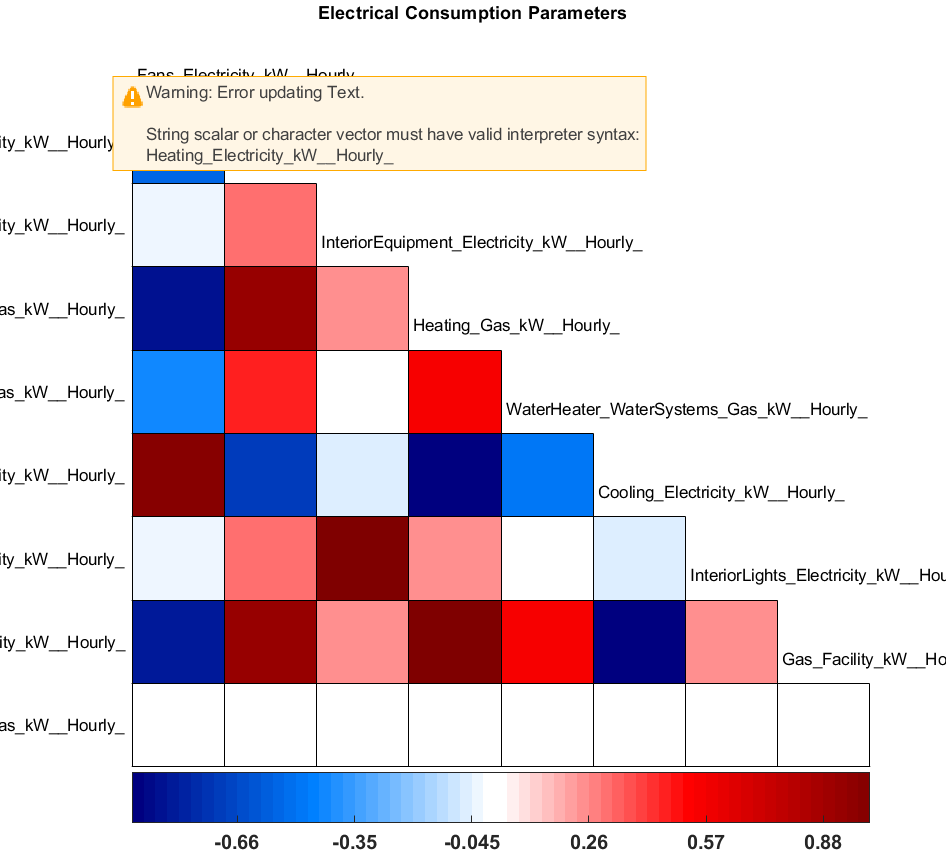

NewDataFeatures = 1.0e+04 *

    0.2385    0.0277    0.7606    0.9559    1.2362    3.9954    2.8429    0.2884    0.8641
    0.2330    0.0406    0.4441    0.9559    1.2362    3.4625    2.3095    0.2884    0.8647
    0.2302    0.0471    0.2678    0.9585    1.2365    3.2113    2.0587    0.2884    0.8642
    0.2300    0.0611    0.1661    0.9559    1.2362    2.9754    1.8224    0.2884    0.8646
    0.2334    0.1025    0.0620    0.9559    1.2362    2.5938    1.4414    0.2884    0.8641
    0.2379    0.1468    0.0032    0.9559    1.2362    2.2026    1.0495    0.2884    0.8647
    0.2530    0.2678         0    0.9533    1.2360    1.6855    0.5319    0.2884    0.8652
    0.2601    0.3294         0    0.9559    1.2362    1.5360    0.3835    0.2884    0.8641
    0.2686    0.4127         0    0.9559    1.2362    1.3668    0.2317    0.2884    0.8467
    0.2730    0.4544         0    0.9585    1.2365    1.2720    0.1631    0.2884    0.8205


NewFeaturesLabels = 1×9 cell array
    {'Fans_Electricity_kW__Hourly_'}    {'Cooling_Electricity_kW__Hourly_'}    {'Heating_Electricity_kW__Hourly_'}    {'InteriorLights_Electricity_kW__Hourly_'}    {'InteriorEquipment_Electricity_kW__Hourly_'}    {'Gas_Facility_kW__Hourly_'}    {'Heating_Gas_kW__Hourly_'}    {'InteriorEquipment_Gas_kW__Hourly_'}    {'WaterHeater_WaterSystems_Gas_kW__Hourly_'}



LabelsRemove =

  1×0 empty cell array



%Maximum correlation value allowed
% Dafault 0.75
threshold = 1;

% El numero de variables a analizar debe ser igual al numero de nombres de
% variables
Features_labels=cellstr(varnames(2:end)');
%corrcoef(input)

% Example:
% a=[1:10];b=a+3;c=a.*b;
% corrcoef([a b c])
% 1.0000    1.0000    0.9816
% 1.0000    1.0000    0.9816
% 0.9816    0.9816    1.0000

[NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(inputDias,Features_labels,threshold)

%Variables eliminadas por superarf el threshold
LabelsRemove'


ans =

  0×1 empty cell array



%variables que se quedan por no superan el threshold en coreelacion
NewFeaturesLabels'

ans = 9×1 cell array
    {'Fans_Electricity_kW__Hourly_'             }
    {'Cooling_Electricity_kW__Hourly_'          }
    {'Heating_Electricity_kW__Hourly_'          }
    {'InteriorLights_Electricity_kW__Hourly_'   }
    {'InteriorEquipment_Electricity_kW__Hourly_'}
    {'Gas_Facility_kW__Hourly_'                 }
    {'Heating_Gas_kW__Hourly_'                  }
    {'InteriorEquipment_Gas_kW__Hourly_'        }
    {'WaterHeater_WaterSystems_Gas_kW__Hourly_' }


clear threshold Features_labels LabelsRemove;

## **Paso 10- Seleccionar el algortimo de ML con un menos error de prediccion empleando el toolbox de Matlab Regression Learner**

% Concatenando la variables de entrada actual con 
% la salida al dia siguiente
DataRegression=[NewDataFeatures(1:end-1,:) outputDias(2:end,1)];
regressionLearner

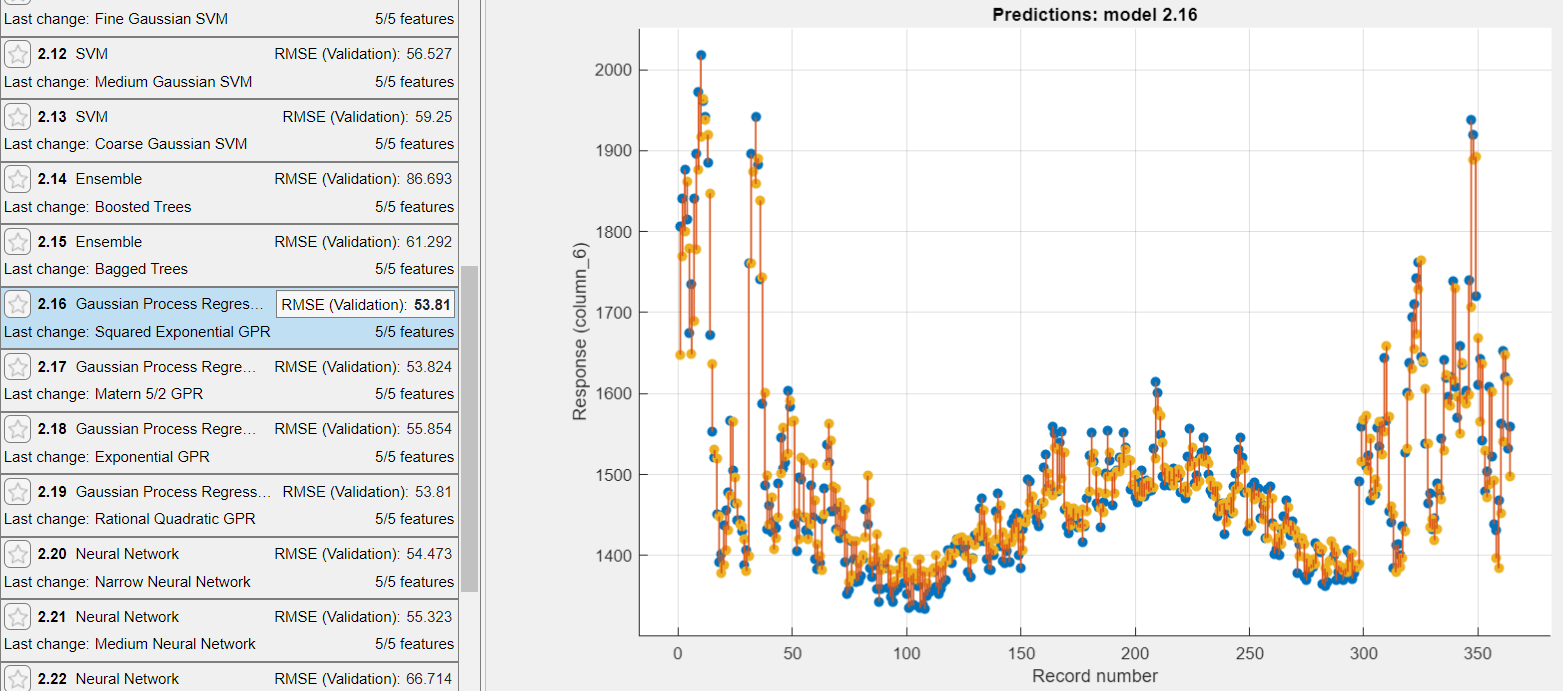    

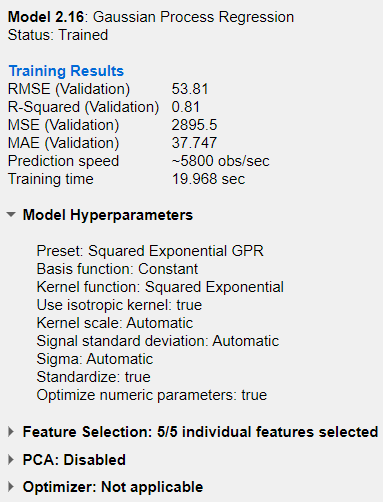

      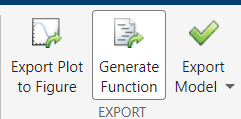

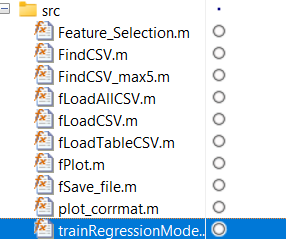

## **Paso 11- Dividir el dataset en 70% para entrenar y 30% validar**

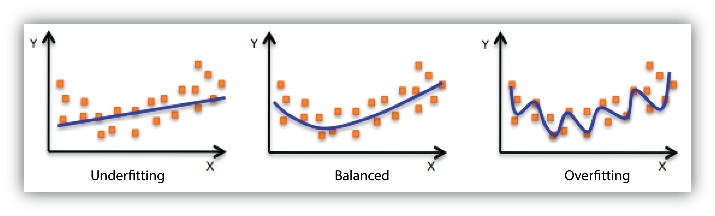

%Set de % de entrenamiento
% Dafault 0.70
PSplit = 0.6;

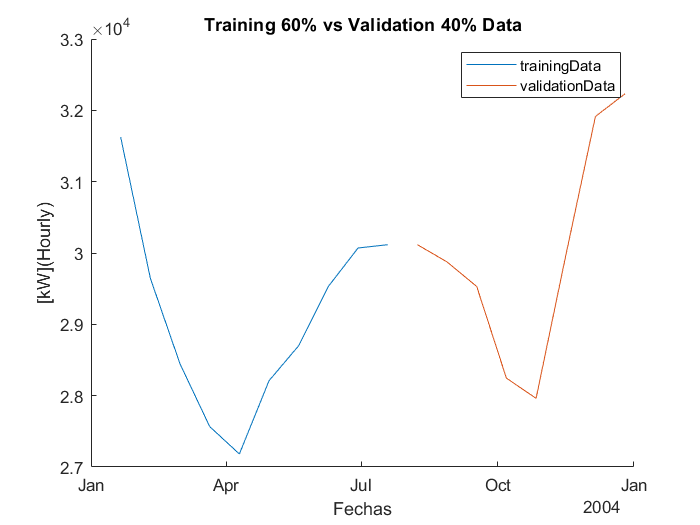

% Dataset de entrenamiento 70%
trainingData=DataRegression(1:round(end*PSplit),:);
traninTime=timeDias(1:round(end*PSplit));
%Calcular el minimo numero de filas entre Data y Time
nfilas=min([size(trainingData,1) size(traninTime,1)]);
%Tomamos el valor minimo de nfilas como maixmo de filas
trainingData=trainingData(1:nfilas,:);
traninTime=timeDias(1:nfilas,:);

% Dataset de validcion 30%
validationData=DataRegression(round(end*PSplit):end,:);
validationTime=timeDias(round(end*PSplit):end);
%Calcular el minimo numero de filas entre Data y Time
nfilas=min([size(validationData,1) size(validationTime,1)]);
%Tomamos el valor minimo de nfilas como maixmo de filas
validationData=validationData(1:nfilas,:);
validationTime=validationTime(1:nfilas,:);

figure;
% Dataset
hold on
plot(traninTime,trainingData(:,end))
plot(validationTime,validationData(:,end))
hold off
title(['Training ' num2str(PSplit*100) '% vs Validation '...
    num2str(100-PSplit*100) '% Data']);
xlabel('Fechas')
ylabel('[kW](Hourly)')
legend('trainingData','validationData')

clear PSplit;

## **Paso 12- Usando el algoritmo de ML se entrena el modelo de regression (costo computacional)**

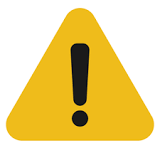

%Esta funcion permite generar un modelo actualizado cada vez que se ejecuta
% Siempre que el numero de variables de entrada sea la misma y la cantidad
% de nuevos datos no sea muy alta
[trainedModel, TrainingRMSE] = trainRegressionModel(trainingData);

%Este es el error de entrenaamiento
TrainingRMSE

TrainingRMSE = 2.6530e+03

%Permite guardar el modelo entrenado que se encuentra en el workspace
save("trainedModel.mat","trainedModel")

## **Paso 13- Cargar y validar el modelo entrenado**

%Cargar el modelo entrenado y guardado
load("trainedModel.mat")

%Usar el modelo entrenado para predecir valores de consumo de energia
yest = trainedModel.predictFcn(validationData(:,1:end-1));

%El valor real de consumo de energia para comparar
yout = validationData(:,end);

%Error de prediccion con datos de validacion [kW](Hourly)
validationRMSE = sqrt(mean((yest - yout).^2))

validationRMSE = 1.7943e+03

%mean absolute percentage error (MAPE)
%min 0% y el maximo 100%
MAPE= mean(abs((yest - yout)./yest))*100

MAPE = 4.7370

## Paso 14 - Graficar el valor predecido vs el valor real

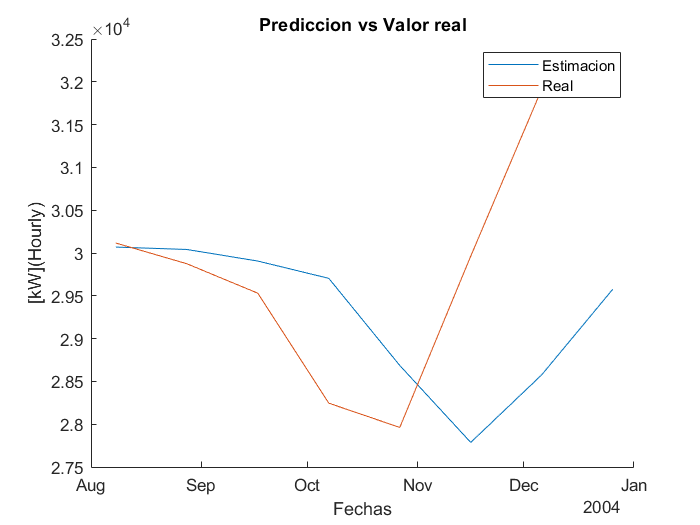

figure;
% Dataset
hold on
plot(validationTime,yest)
plot(validationTime,yout)
title('Prediccion vs Valor real');
xlabel('Fechas')
ylabel('[kW](Hourly)')
legend('Estimacion','Real')

## Paso 15 - Mejorar el modelo de prediccion

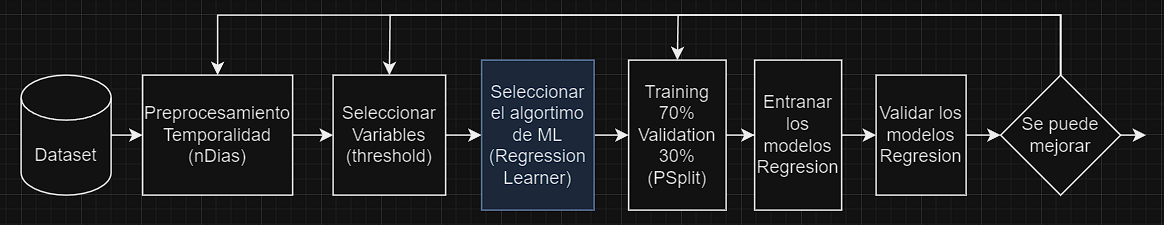

# INFORME DE RESULTADOS

**Con el dataset USA_AK_FAIRBANKS.csv se llegaron a obtener los siguientes Resultados:**

## **Predicciones de dias**

- Al tener mas dias y por tanto mas ejemplos, la redundancia de las variables de entrada se vuelve contraproducente. Es decir, al usar un threshold=0.75 se eliminaron 4 variables de entrada y esto mejoro la prediccion del modelo de regresion.

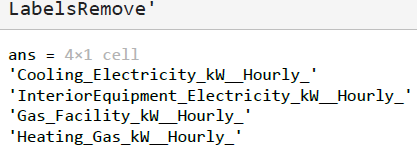

- Segun el regression learner de matlab el mejor algoritmo de prediccion es un Gaussian Process Regression:

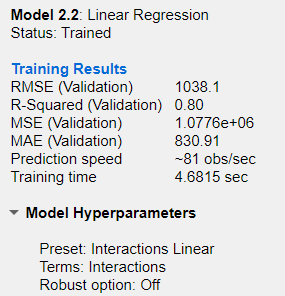

- Con un valor de PSplit de 0.6, es decir 60% de lso datos de entrenamiento y 40% de los datos de validiacion. En la validacion del modelo se obtiene: RMSE: 59.34 [kW](Hourly) y MAPE: 2.9%

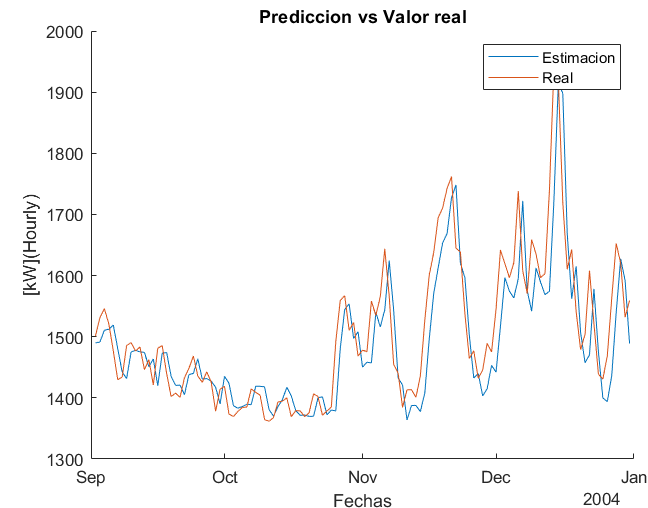

## **Predicciones de 30 dias**

- Para predicciones de meses, al tener solo 12, se vuelve necesario tener mas informacion por parte de las variables de entrada. Es decir, no importa la redundancia en las variables de entrada de la informacion por que ayudara a que el modelo tenga un menor error. En este ejemplo, se puso un threshold=0 y el eror de prediccion se vio decrementado.

- Con prediccion de 30 dias, se uso un threshold = 100% para no eliminar ninguna de las variables.

- Segun el regression learner de matlab el mejor algoritmo de prediccion es un Stepwise Lienar regression:

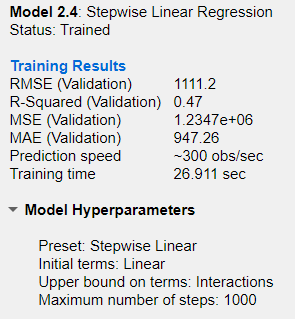

- Con un valor de PSplit de 0.6, es decir 60% de lso datos de entrenamiento y 40% de los datos de validiacion. En la validacion del modelo se obtiene: RMSE: 1794 [kW](Hourly) y MAPE: 4.7%

- Nota: Con el valor de PSplit de 0.6, el error de entrenamiento fue de 2753 [kW](Hourly), mayor que el de validacion. Esto se debe a que el comportaiento de la variable en el 60% de los datos de entrenamiento, tiene un comportamiento mas variiable que el presneatdo en el restante 40% de los datos de validacion.